% problema 1

interpolareLagrange([3 4 5], [6 7 8], 4)

ans = 7

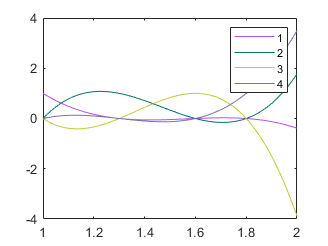


% problema 2

nodes = [1 1.3 1.6 1.8];
m = 4;

labels = {};
for k = 1 : m
    t = 1 : 0.01 : 2;
    p = evaluarePolinomFundamentalMultiplePoints(nodes, k, t);
    labels = [labels num2str(k)];
    plot(t, p, 'color', rand(1,3))
    hold on;
end
legend(labels);
hold off;

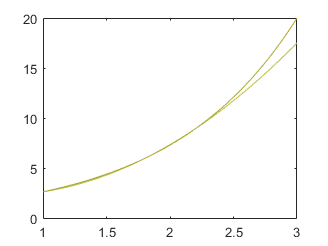


% problema 3
nodes = [1, 1.8, 2.2];
nodevals = exp(nodes);

t = 1 : 0.01 : 3;
res = interpolareLagrangeMultiplePoints(nodes, nodevals, t);

plot(t, res, 'color', rand(1,3));
hold on;

resexp = exp(t);
plot(t, resexp, 'color', rand(1,3));
hold off;


% problema 4
% Definirea punctelor de interpolare
nodes = [0, pi/2, pi, 3*pi/2, 2*pi]; % Punctele echidistante de la 0 la 2*pi

% Definirea funcției sinus
f = @(x) sin(x);

% Punctul la care dorim să aproximăm valoarea funcției sinus
x = 1.2;

% Gradul de interpolare
m = 3;

% Aproximarea valorii funcției sinus la punctul x folosind interpolarea Lagrange
approx_value = interpolareLagrangeFdat(x, f, m, nodes);

% Calculul valorii reale a funcției sinus la punctul x
real_value = f(x);

% Afișarea rezultatelor
fprintf('Aproximare folosind interpolarea Lagrange: %.6f\n', approx_value);

Aproximare folosind interpolarea Lagrange: 0.944277


fprintf('Valoare reală a funcției sinus la x=%.1f: %.6f\n', x, real_value);

Valoare reală a funcției sinus la x=1.2: 0.932039



% problema 5
baryLagrange([1 1.5 2], [exp(1) exp(1.5) exp(2)], 1.2)

ans = 3.2864

exp(1.2)

ans = 3.3201


%problema 1 practica
interpolareLagrange([1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010], [75.995 91.972 105.711 123.203 131.669 150.697 179.323 203.212 226.505 249.633 281.422 308.786], 1975)

ans = 214.3644

interpolareLagrange([1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010], [75.995 91.972 105.711 123.203 131.669 150.697 179.323 203.212 226.505 249.633 281.422 308.786], 2018)

ans = -664.3068

interpolareLagrange([1980 1990 2000 2010], [226.505 249.633 281.422 308.786], 2018)

ans = 318.6974


%problema 2 practica
f = @(x)exp(x.^2 - 1);
pb2p = interpolareLagrangeFdat(1.25, f, 4, [1 1.1 1.2 1.3 1.4])

pb2p = 1.7557

fprintf("Real: %f", exp(1.25.^2 - 1));

Real: 1.755055

err = abs(pb2p - exp(1.25.^2 - 1))

err = 6.2007e-04


%problema 3 practica
interpolareLagrangeFdat(115, @sqrt, 4, [100 113 121 144])

ans = 10.7238

sqrt(115)

ans = 10.7238


%problema 4 practica
disp('problema 4')

problema 4


disp('Runge')

Runge


f = @(x) 1./(1 + x.^2);

% Noduri echidistante
nodes_eq = linspace(-5, 5, 11); 
nodevals_eq = f(nodes_eq);

% Noduri Cebîșev de speța a doua
nodes_ceb = cos((2*(1:11) - 1) * pi / (2*11));
nodevals_ceb = f(nodes_ceb);

t = linspace(-5, 5, 1000);

% Interpolare cu noduri echidistante
resexp_eq = interpolareLagrangeMultiplePoints(nodes_eq, nodevals_eq, t)

resexp_eq =     0.0385    0.1924    0.3379    0.4752    0.6047    0.7267    0.8412    0.9488    1.0494    1.1435    1.2312    1.3127    1.3883    1.4583    1.5227    1.5818    1.6359    1.6851    1.7295    1.7695    1.8051    1.8365    1.8639    1.8876    1.9075    1.9240    1.9371    1.9470    1.9539    1.9578    1.9589    1.9575    1.9534    1.9470    1.9384    1.9275    1.9147    1.8999    1.8833    1.8650    1.8450    1.8236    1.8007    1.7765    1.7511    1.7245    1.6969    1.6682    1.6387    1.6083



% Interpolare cu noduri Cebîșev de speța a doua
resexp_ceb = interpolareLagrangeMultiplePoints(nodes_ceb, nodevals_ceb, t)

resexp_ceb = 	1.0e+06 *

   -1.0592   -1.0375   -1.0163   -0.9954   -0.9749   -0.9548   -0.9351   -0.9158   -0.8968   -0.8781   -0.8598   -0.8419   -0.8243   -0.8070   -0.7900   -0.7734   -0.7571   -0.7410   -0.7253   -0.7099   -0.6948   -0.6800   -0.6655   -0.6512   -0.6372   -0.6235   -0.6100   -0.5968   -0.5839   -0.5712   -0.5588   -0.5466   -0.5347   -0.5229   -0.5115   -0.5002   -0.4892   -0.4783   -0.4677   -0.4573   -0.4472   -0.4372   -0.4274   -0.4178   -0.4084   -0.3992   -0.3902   -0.3814   -0.3727   -0.3642


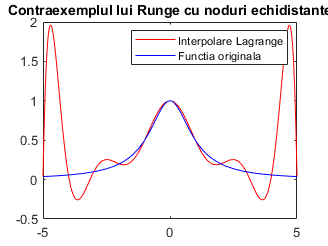

fff1=f(t);
figure;
plot(t, resexp_eq, 'r', t, f(t), 'b');
title('Contraexemplul lui Runge cu noduri echidistante');
legend('Interpolare Lagrange', 'Functia originala');

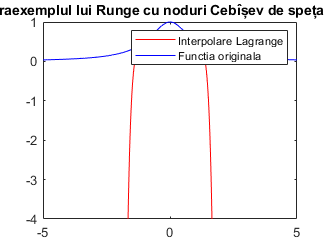


fff2=f(t);
figure;
plot(t, resexp_ceb, 'r', t, f(t), 'b');
title('Contraexemplul lui Runge cu noduri Cebîșev de speța a doua');
legend('Interpolare Lagrange', 'Functia originala');
ylim([-4, 1]);

if (fff1 == fff2)
    fprintf('da');
end

da


disp('Bernstein')

Bernstein


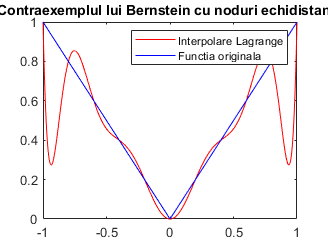

g = @(x) abs(x);

% Noduri echidistante
nodes_eq = linspace(-1, 1, 11); 
nodevals_eq = g(nodes_eq);

% Noduri Cebîșev de speța a doua
nodes_ceb = cos((2*(1:11) - 1) * pi / (2*11));
nodevals_ceb = g(nodes_ceb);

t = linspace(-1, 1, 1000);

% Interpolare cu noduri echidistante
res_eq = interpolareLagrangeMultiplePoints(nodes_eq, nodevals_eq, t);

% Interpolare cu noduri Cebîșev de speța a doua
res_ceb = interpolareLagrangeMultiplePoints(nodes_ceb, nodevals_ceb, t);

figure;
plot(t, res_eq, 'r', t, g(t), 'b');
title('Contraexemplul lui Bernstein cu noduri echidistante');
legend('Interpolare Lagrange', 'Functia originala');

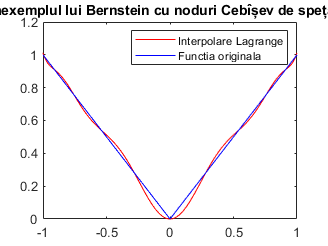


figure;
plot(t, res_ceb, 'r', t, g(t), 'b');
title('Contraexemplul lui Bernstein cu noduri Cebîșev de speța a doua');
legend('Interpolare Lagrange', 'Functia originala');


% problema 5 practica

disp('sin')

sin


interpolareLagrangeFdat(deg2rad(5), @sin, 4, [pi/6 pi/4 pi/3 pi/2])

ans = 0.0744

sin(deg2rad(5))

ans = 0.0872


disp('cos')

cos


interpolareLagrangeFdat(deg2rad(5), @cos, 4, [pi/6 pi/4 pi/3 pi/2])

ans = 0.9839

cos(deg2rad(5))

ans = 0.9962